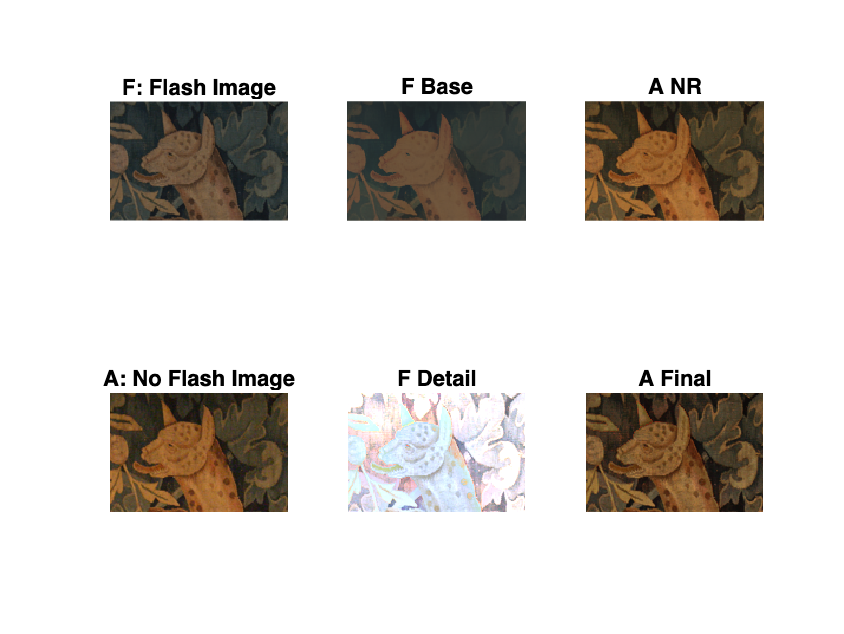

%Demonstration Filter
figure; 
tiledlayout(2,3,"TileSpacing","tight");
%A_final_20 = {A_final,F_base,F_detail,A_base,A_NR};

A_final = A_final_20{1,1};
F_base = A_final_20{1,2};
F_detail = A_final_20{1,3};
A_base = A_final_20{1,4};
A_NR = A_final_20{1,5};

nexttile
imshow(flash_img(120:220,300:450,:));
title("F: Flash Image")

nexttile
imshow(uint8(F_base(120:220,300:450,:)));
title("F Base")

nexttile
imshow(uint8(A_NR(120:220,300:450,:)));
title("A NR")

nexttile
imshow(noflash_img(120:220,300:450,:));
title("A: No Flash Image")

nexttile
imshow(F_detail(120:220,300:450,:));
title("F Detail")

nexttile
imshow(uint8(A_final(120:220,300:450,:)));
title("A Final")

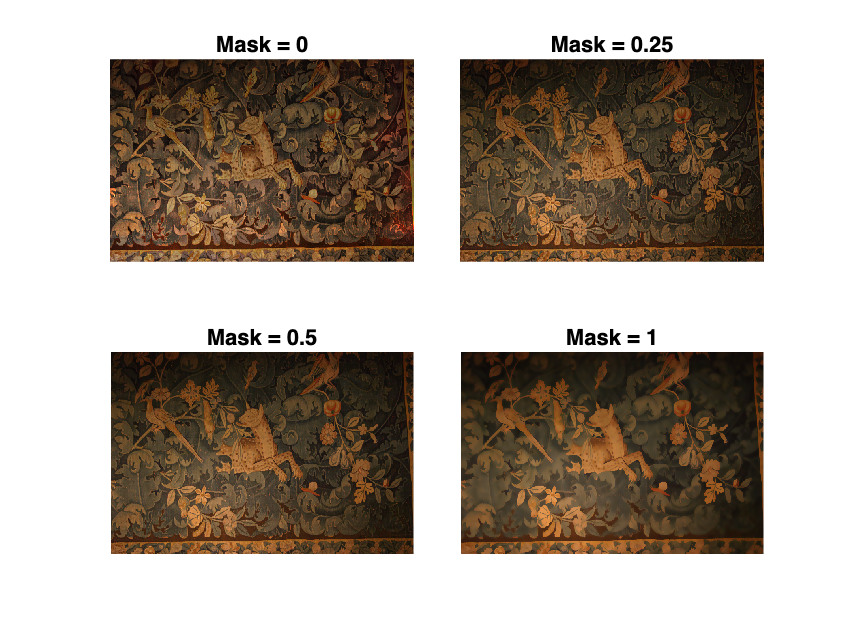


%Mask Variation Figure
figure; 
sgtitle("Varying Mask Value")
tiledlayout(2,2,"TileSpacing","tight");
nexttile
imshow(uint8(A_final_5{1,1}))
title("Mask = 0")
nexttile
imshow(uint8(A_final_Maskp25{1,1}))
title("Mask = 0.25")
nexttile
imshow(uint8(A_final_Maskp5{1,1}))
title("Mask = 0.5")
nexttile
imshow(uint8(A_final_Mask1{1,1}))
title("Mask = 1")

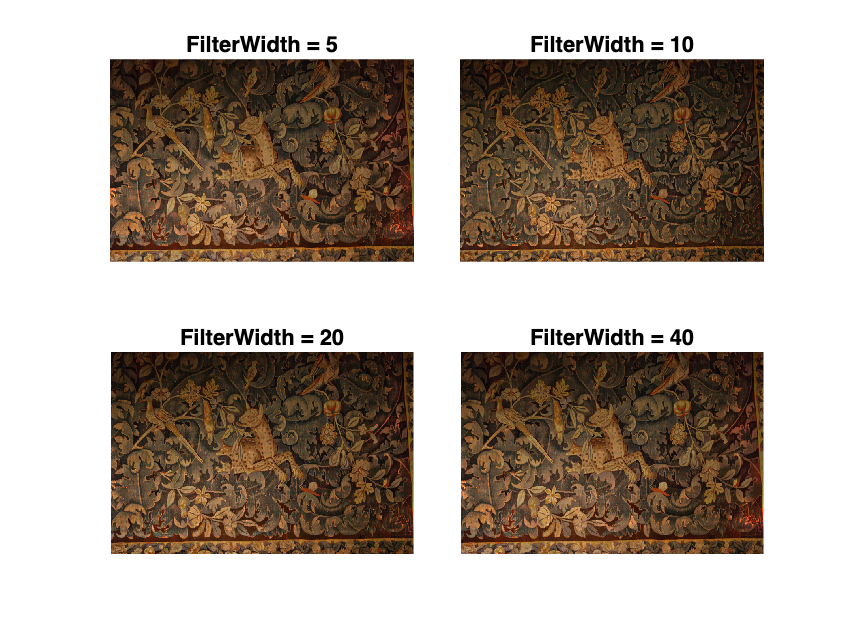

%Filter Width Figure
figure; 
sgtitle("Varying Filter Width")
tiledlayout(2,2,"TileSpacing","tight");
nexttile
imshow(uint8(A_final_5{1,1}))
title("FilterWidth = 5")
nexttile
imshow(uint8(A_final_10{1,1}))
title("FilterWidth = 10")
nexttile
imshow(uint8(A_final_20{1,1}))
title("FilterWidth = 20")
nexttile
imshow(uint8(A_final_40{1,1}))
title("FilterWidth = 40")

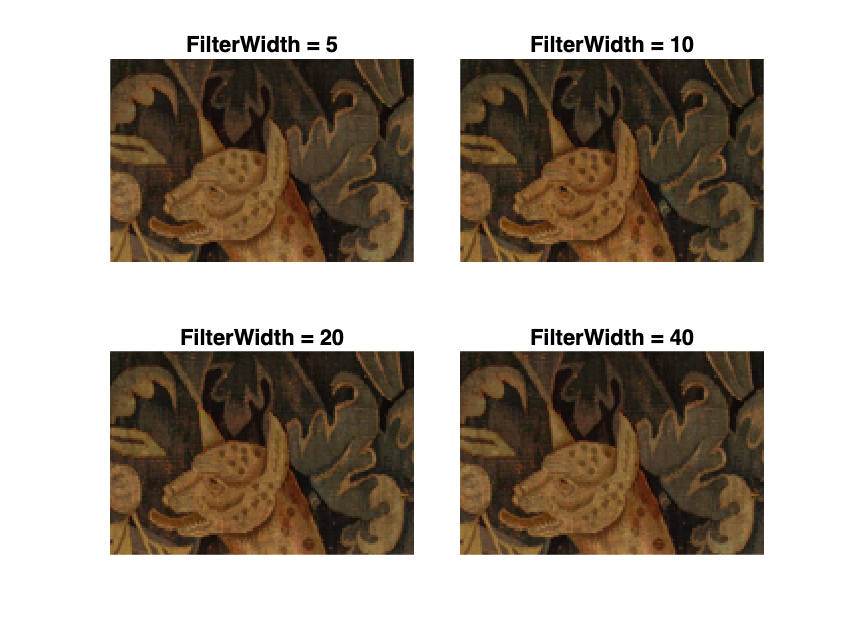

%Filter Width Figure
figure; 
sgtitle("Varying Filter Width")
tiledlayout(2,2,"TileSpacing","tight");
nexttile; 
imshow(uint8(A_final_5{1,1}(100:200,300:450,:)))
title("FilterWidth = 5")
nexttile
imshow(uint8(A_final_10{1,1}(100:200,300:450,:)))
title("FilterWidth = 10")
nexttile
imshow(uint8(A_final_20{1,1}(100:200,300:450,:)))
title("FilterWidth = 20")
nexttile
imshow(uint8(A_final_40{1,1}(100:200,300:450,:)))
title("FilterWidth = 40")

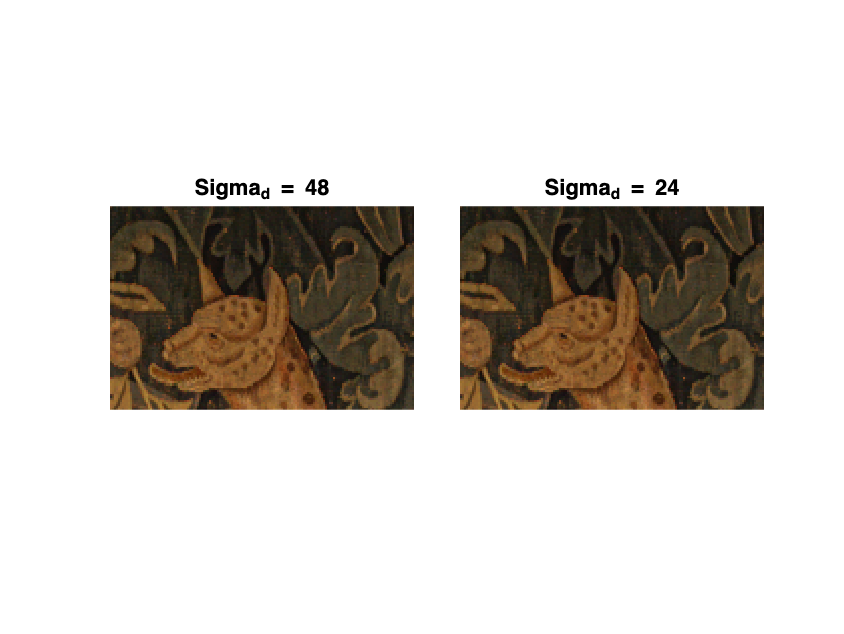

%Sigmad Figure
figure; 
sgtitle("Varying Filter Width")
tiledlayout(1,2,"TileSpacing","tight");
nexttile
imshow(uint8(A_final_5{1,1}(100:200,300:450,:)))
title("Sigma_d = 48")
nexttile
imshow(uint8(A_final_sigmad_24{1,1}(100:200,300:450,:)))
title("Sigma_d = 24")

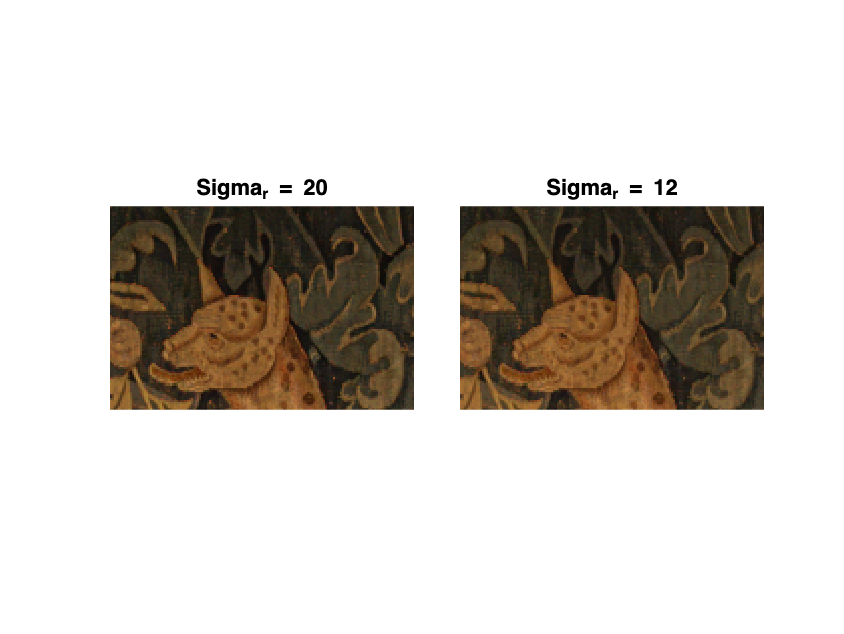

%Sigmar Figure
% figure; 
%sgtitle("Varying Filter Width")
tiledlayout(1,2,"TileSpacing","tight");
nexttile
imshow(uint8(A_final_5{1,1}(100:200,300:450,:)))
title("Sigma_r = 20")
nexttile
imshow(uint8(A_final_sigmar_bilat_12{1,1}(100:200,300:450,:)))
title("Sigma_r = 12")

%Zoomed in Figure to show Detail

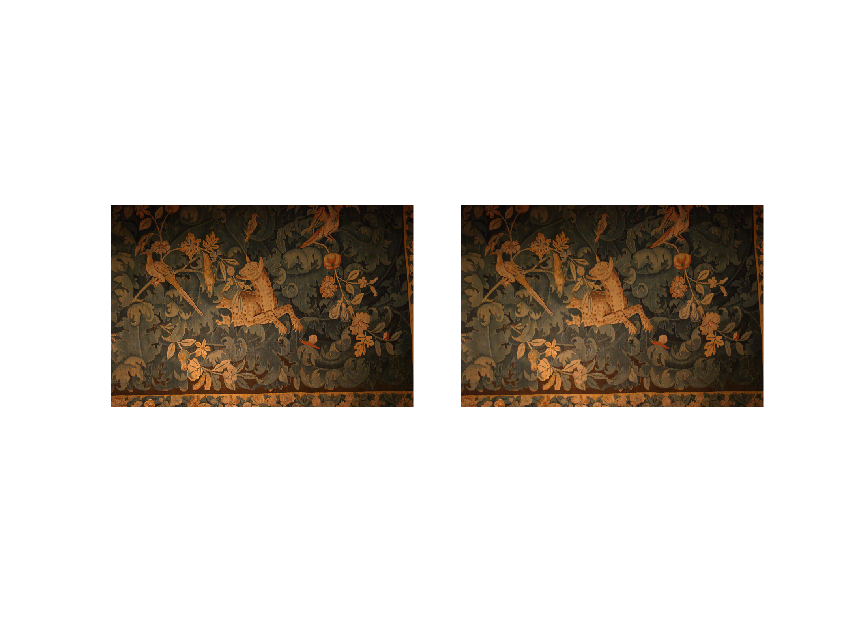

%Comparison with their images
filepath = '/Users/abbyskerker/Documents/Spring24/EC520/Project/flash_data_JBF_Detail_transfer/flash_data_JBF_Detail_transfer/';
filename_theirs = 'carpet_03_our_result.tif';
fn = strcat(filepath,filename_theirs);
their_img = (imread(fn)); 
magnificationFactor = .25; 
their_img = imresize(their_img,magnificationFactor);

figure; 
tiledlayout(1,2,"TileSpacing","tight");
nexttile
imshow(their_img)
%A_final_20 = {A_final,F_base,F_detail,A_base,A_NR};
nexttile
A_final = A_final_sigmad_24{1,5};
imshow(uint8(A_final))